# Task 2: Two spins-1 under a magnetic field

The problem of two non-interacting (and identical) spin S = 1 particles under a magnetic field along the z-axis is described by the Hamiltonian		


$$\mathcal{H} = -\gamma B S_z$$


where $\gamma$ is the gyromagnetic ratio of the particles, $B$ is the amplitude of the field, and $S_z=S_{1z}+S_{2z}$.

# Subtask a

Write a few lines of code that deliver the matrix representations of the operators $$S_{1z}$$, $$S_{2z}$$ and $$S_{z}$$ in the `product-Sz basis'$$\{|S_1,M_1\rangle \otimes|S_2,M_2\rangle\}$.$ 

[Sx, Sy, Sz]=FetchSpinMatrices(1);
Sx1 = kron(Sx,eye(3));
Sx2 = kron(eye(3),Sx);
Sy1 = kron(Sy,eye(3));
Sy2 = kron(eye(3),Sy);
Sz1 = kron(Sz,eye(3))

Sz1 =      1     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -1     0     0
     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0    -1


Sz2 = kron(eye(3),Sz)

Sz2 =      1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    -1     0     0     0
     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0    -1


Sx = Sx1 + Sx2;
Sy = Sy1 + Sy2;
Sz = Sz1 + Sz2

Sz =      2     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    -1     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0    -2


# Subtask b

Write a few lines of code that deliver the matrix representation of $$\mathcal{H}$$ for $$\gamma B=1$$. Solve the Schroedinger equation (eigenvalue matrix equation) to obtain the energy eigenvalues and the corresponding eigenstates of $$\mathcal{H}$$. Obtain the quantum mechanical expectation values of the nine operators$ $\{S_{1x}, S_{1y}, S_{1z}, S_{2x}, S_{2y}, S_{2z}, S_x=S_{1x}+S_{2x}, S_y=S_{1y}+S_{2y}, S_z=S_{1z}+S_{2z}\}$$ in each energy eigenstate separately.

Hamiltonian = -1 * Sz

Hamiltonian =     -2     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     2


[V,D] = eig(Hamiltonian)

V =      1     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0
     0     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     1


D =     -2     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     2


Energy = eig(Hamiltonian);
EigState1 = V(:,1)

EigState1 =      1
     0
     0
     0
     0
     0
     0
     0
     0


Energy1 = Energy(1)

Energy1 = -2

EigState2 = V(:,2)

EigState2 =      0
     1
     0
     0
     0
     0
     0
     0
     0


Energy2 = Energy(2)

Energy2 = -1

EigState3 = V(:,3)

EigState3 =      0
     0
     0
     1
     0
     0
     0
     0
     0


Energy3 = Energy(3)

Energy3 = -1

EigState4 = V(:,4)

EigState4 =      0
     0
     1
     0
     0
     0
     0
     0
     0


Energy4 = Energy(4)

Energy4 = 0

EigState5= V(:,5)

EigState5 =      0
     0
     0
     0
     1
     0
     0
     0
     0


Energy5 = Energy(5)

Energy5 = 0

EigState6 = V(:,6)

EigState6 =      0
     0
     0
     0
     0
     0
     1
     0
     0


Energy6 = Energy(6)

Energy6 = 0

EigState7 = V(:,7)

EigState7 =      0
     0
     0
     0
     0
     1
     0
     0
     0


Energy7 = Energy(7)

Energy7 = 1

EigState8 = V(:,8)

EigState8 =      0
     0
     0
     0
     0
     0
     0
     1
     0


Energy8 = Energy(8)

Energy8 = 1

EigState9 = V(:,9)

EigState9 =      0
     0
     0
     0
     0
     0
     0
     0
     1


Energy9 = Energy(9)

Energy9 = 2

for i = 1:9
    Ei = V(:,i);
ExpectationSx1 = Ei' * Sx1 * Ei
ExpectationSx2 = Ei' * Sx2 * Ei
ExpectationSy1 = Ei' * Sy1 * Ei
ExpectationSy2 = Ei' * Sy2 * Ei
ExpectationSz1 = Ei' * Sz1 * Ei
ExpectationSz2 = Ei' * Sz2 * Ei
ExpectationSx = Ei' * Sx * Ei
ExpectationSy = Ei' * Sy * Ei
ExpectationSz = Ei' * Sz * Ei
end

ExpectationSx1 = 0

ExpectationSx2 = 0

ExpectationSy1 = 0

ExpectationSy2 = 0

ExpectationSz1 = 1

ExpectationSz2 = 1

ExpectationSx = 0

ExpectationSy = 0

ExpectationSz = 2

ExpectationSx1 = 0

ExpectationSx2 = 0

ExpectationSy1 = 0

ExpectationSy2 = 0

ExpectationSz1 = 1

ExpectationSz2 = 0

ExpectationSx = 0

ExpectationSy = 0

ExpectationSz = 1

ExpectationSx1 = 0

ExpectationSx2 = 0

ExpectationSy1 = 0

ExpectationSy2 = 0

ExpectationSz1 = 0

ExpectationSz2 = 1

ExpectationSx = 0

ExpectationSy = 0

ExpectationSz = 1

ExpectationSx1 = 0

ExpectationSx2 = 0

ExpectationSy1 = 0

ExpectationSy2 = 0

ExpectationSz1 = 1

ExpectationSz2 = -1

ExpectationSx = 0

ExpectationSy = 0

ExpectationSz = 0

ExpectationSx1 = 0

ExpectationSx2 = 0

ExpectationSy1 = 0

ExpectationSy2 = 0

ExpectationSz1 = 0

ExpectationSz2 = 0

ExpectationSx = 0

ExpectationSy = 0

ExpectationSz = 0

ExpectationSx1 = 0

ExpectationSx2 = 0

ExpectationSy1 = 0

ExpectationSy2 = 0

ExpectationSz1 = -1

ExpectationSz2 = 1

ExpectationSx = 0

ExpectationSy = 0

ExpectationSz = 0

ExpectationSx1 = 0

ExpectationSx2 = 0

ExpectationSy1 = 0

ExpectationSy2 = 0

ExpectationSz1 = 0

ExpectationSz2 = -1

ExpectationSx = 0

ExpectationSy = 0

ExpectationSz = -1

ExpectationSx1 = 0

ExpectationSx2 = 0

ExpectationSy1 = 0

ExpectationSy2 = 0

ExpectationSz1 = -1

ExpectationSz2 = 0

ExpectationSx = 0

ExpectationSy = 0

ExpectationSz = -1

ExpectationSx1 = 0

ExpectationSx2 = 0

ExpectationSy1 = 0

ExpectationSy2 = 0

ExpectationSz1 = -1

ExpectationSz2 = -1

ExpectationSx = 0

ExpectationSy = 0

ExpectationSz = -2

# Subtask c

Plot of the energy spectrum vs $\gamma B$ in the range $\gamma B \in [-3,3]$.

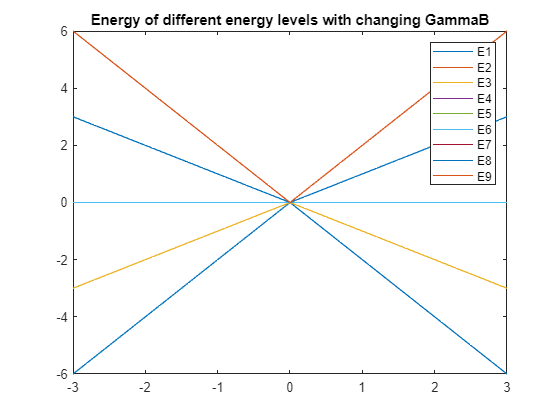

%add your code here
E1 = [];
E2 = [];
E3 = [];
E4 = [];
E5 = [];
E6 = [];
E7 = [];
E8 = [];
E9 = [];

for gammaB = -3:0.1:3;
    Hamiltonian = -1*(gammaB)*Sz;
    Energy = eig(Hamiltonian);
    E1 = [E1 Energy(1)];
    E2 = [E2 Energy(2)];
    E3 = [E3 Energy(3)];
    E4 = [E4 Energy(4)];
    E5 = [E5 Energy(5)];
    E6 = [E6 Energy(6)];
    E7 = [E7 Energy(7)];
    E8 = [E8 Energy(8)];
    E9 = [E9 Energy(9)];
end;
y = -3:0.1:3;
plot(y,E1)
hold on
plot(y,E2)
hold on
plot(y,E3)
hold on
plot(y,E4)
hold on
plot(y,E5)
hold on
plot(y,E6)
hold on
plot(y,E7)
hold on
plot(y,E8)
hold on
plot(y,E9)
hold on
legend('E1','E2','E3','E4','E5','E6','E7','E8','E9')
title("Energy of different energy levels with changing GammaB")
hold off

# Subtask d

Plot the ${\bf ground~state}$ expectation value of the operator $S_z$ vs $\gamma B$ in the range $\gamma B \in [-3,3]$.

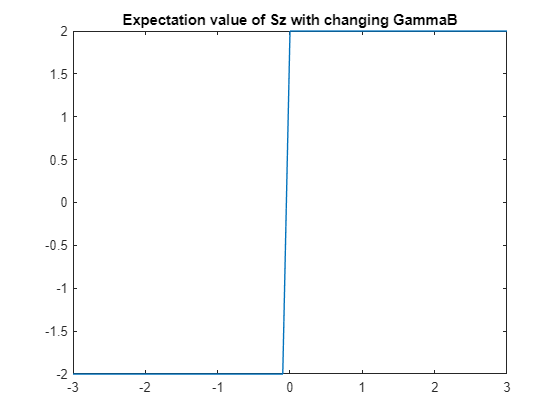

%add your code here
ExpectationSz = [];
for gammaB = -3:0.1:3;
    Hamiltonian = -1*(gammaB)*Sz;
    [V,D] = eig(Hamiltonian);
    E1 = V(:,1);
    E1ExpectationSz = E1' * Sz * E1;
    ExpectationSz = [ExpectationSz E1ExpectationSz];
end
ExpectationSz;
x = -3:0.1:3;
plot(x,ExpectationSz)
title("Expectation value of Sz with changing GammaB")

Function for finding spin matracies as provided

function [Sx, Sy, Sz, Sp, Sm]=FetchSpinMatrices(S)

%sanity check
if rem(2*S,1)~=0; 
 disp('please provide an integer or half-integer value for S'); 
 return; 
end

dim=2*S+1; %dimension of Hilbert space

%initialize the matrices
Sx=zeros(dim,dim); Sy=zeros(dim,dim); Sz=zeros(dim,dim); Sp=zeros(dim,dim); Sm=zeros(dim,dim);


j=0;
for m=S:-1:-S; j=j+1;

 %Sz matrix
 Sz(j,j)=m;

 %Sp matrix
 f1=sqrt(S*(S+1)-m*(m+1));
 if f1~=0; 
  Sp(j-1,j)=f1; %matrix element between the bra <m+1| (corresponding to index j-1) and ket |m> (corresponding to index j)
 end

 %Sm matrix
 f2=sqrt(S*(S+1)-m*(m-1));
 if f2~=0; 
  Sm(j+1,j)=f2; %matrix element between the bra <m-1| (corresponding to index j+1) and ket |m> (corresponding to index j)
 end

end
Sx=(Sp+Sm)/2;
Sy=(Sp-Sm)/(2*complex(0,1));

return
end